- Lab 5a. Download the training datasets from one of the two  pT-range folders.  In each folder, there are 2 files, each containing 100k jets. The signal dataset is labeled as “higgs” and the background dataset is labeled as  “qcd.”

- Lab 5b. Explore the training data by addressing following questions:

- Do all features provide discrimination power between signal and background? 

- Are there correlations among these features? 

- Compute expected discovery sensitivity by normalizing each sample appropriately. 

- Develop a plan to optimize the discovery sensitivity by applying selections to these features. 

feature_labels = {'pt', 'eta', 'phi', 'mass', 'ee2', 'ee3', 'd2', 'angularity', ...
    't1', 't2', 't3', 't21', 't32', 'KtDeltaR'};

data_index = 1;

qcd_data_labels = ["qcd_100000_pt_250_500", "qcd_100000_pt_1000_1200"];
higgs_data_labels = ["higgs_100000_pt_250_500", "higgs_100000_pt_1000_1200"];

qcd_label = qcd_data_labels(data_index);
higgs_label = higgs_data_labels(data_index);

h5disp("data/" + qcd_label +".h5")

HDF5 qcd_100000_pt_250_500.h5 
Group '/' 
    Dataset 'qcd_100000_pt_250_500' 
        Size:  14x100000
        MaxSize:  14x100000
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000


h5disp("data/" + higgs_label +".h5")

HDF5 higgs_100000_pt_250_500.h5 
Group '/' 
    Dataset 'higgs_100000_pt_250_500' 
        Size:  14x100000
        MaxSize:  14x100000
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000


qcd_data = h5read("data/" + qcd_label+".h5", ['/' convertStringsToChars(qcd_label)]);
higgs_data = h5read("data/" + higgs_label +".h5",['/' convertStringsToChars(higgs_label)]);


## 1. Do all features provide discrimination power between signal and background? 

To examine how the different aspect of the data might be able to discriminate between the Higgs signal and the background, we will examine histograms of each of the 14 types of data for both data sets. Then, we will examine the ratio of the higgs data to the qcd data in the range of the higgs data and plot a ratio of the higgs signal to the background signal over that same range. Histogram bins that have some Higgs signal but no background are set to $10^5$: 

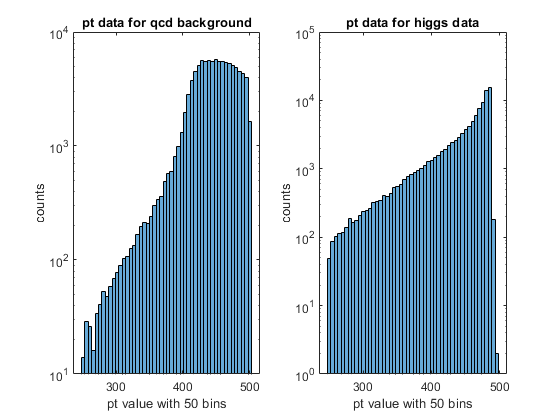

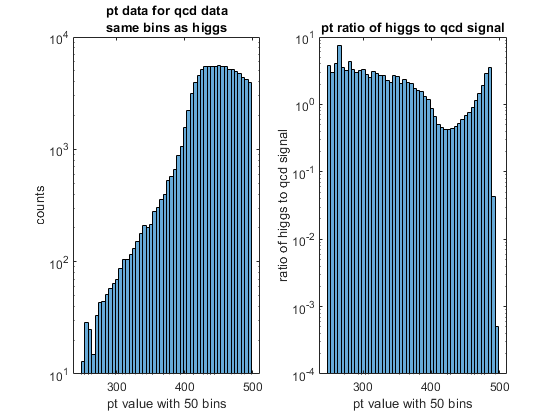

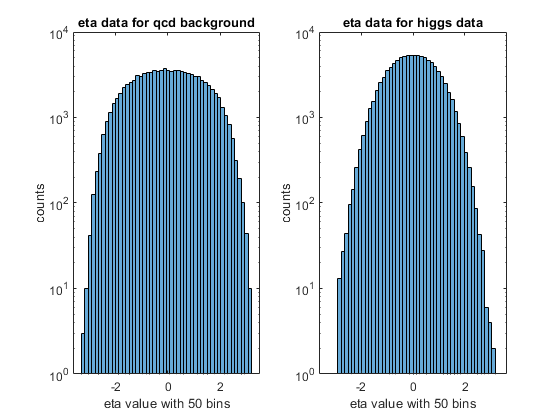

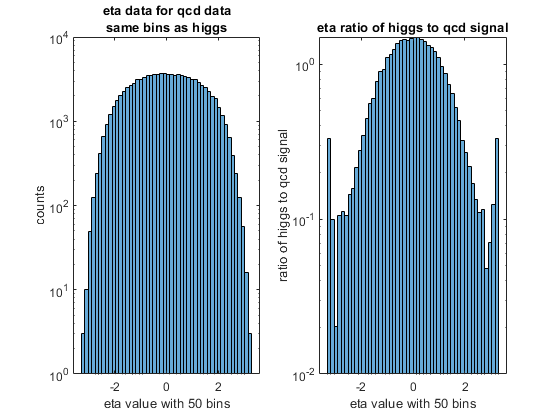

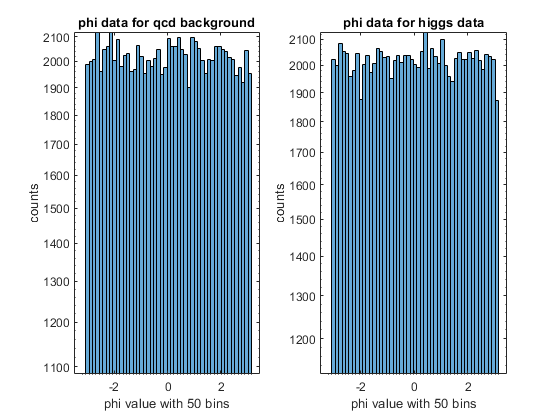

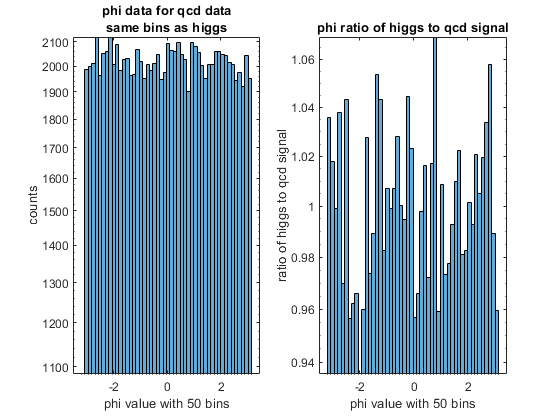

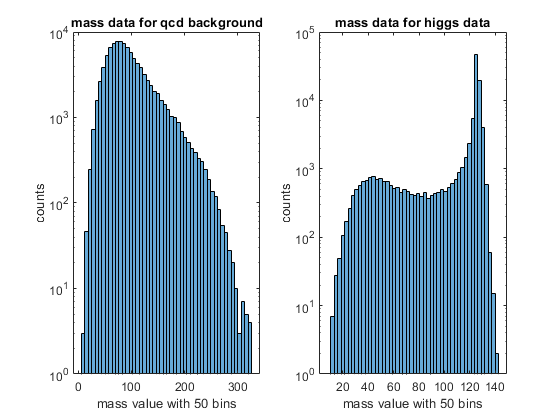

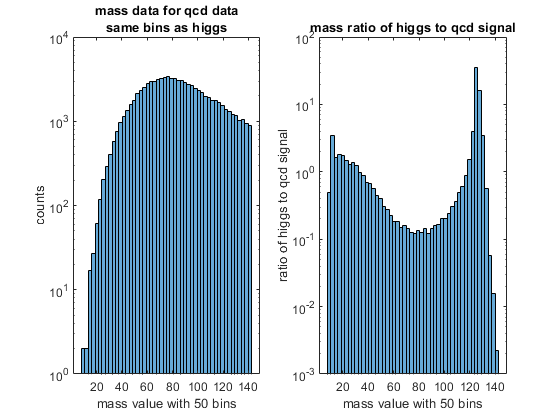



for i=1:length(feature_labels)
    
    label = feature_labels{i};
    nbins = 50;
    figure
    
    subplot(1,2,1)
    qcd_hist = histogram(qcd_data(:, i), nbins);
    title([label ' data for qcd background'])
    xlabel([label ' value with ' num2str(nbins) ' bins'])
    ylabel('counts')
    set(gca, 'Yscale', 'log')
    
    subplot(1,2,2)
    higgs_hist = histogram(higgs_data(:, i), nbins);
    title([label ' data for higgs data'])
    xlabel([label ' value with ' num2str(nbins) ' bins'])
    ylabel('counts')
    set(gca, 'Yscale', 'log')
    
    figure 
    subplot(1,2,1)
    qcd_restricted_hist = histogram(qcd_data(:, i), higgs_hist.BinEdges);
    title({[label ' data for qcd data'], 'same bins as higgs'})
    xlabel([label ' value with ' num2str(nbins) ' bins'])
    ylabel('counts')
    set(gca, 'Yscale', 'log')
    
    subplot(1,2,2)
    ratio_values = higgs_hist.BinCounts ./ (qcd_restricted_hist.BinCounts);
    ratio_values(isinf(ratio_values)) = 10^5;
    ratio_values(isnan(ratio_values)) = 0;
    ratio_hist = histogram('BinEdges', higgs_hist.BinEdges, 'BinCounts',ratio_values);
    title([label ' ratio of higgs to qcd signal'])
    xlabel([label ' value with ' num2str(nbins) ' bins'])
    ylabel('ratio of higgs to qcd signal')
    set(gca, 'Yscale', 'log')
end

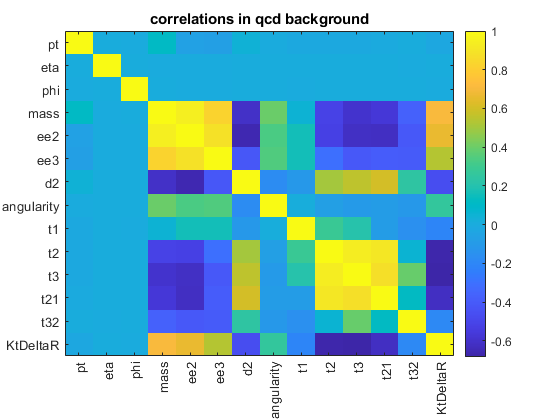


qcd_data_correlations = corrcoef(qcd_data);
higgs_data_correlations = corrcoef(higgs_data);

figure;
imagesc(qcd_data_correlations)
title('correlations in qcd background')
xtick_values = 1:14;
ytick_values = 1:14;
set(gca, 'Xtick', xtick_values, 'XTickLabel', feature_labels)
set(gca, 'Ytick', ytick_values, 'YTickLabel', feature_labels)
xtickangle(90)
colorbar

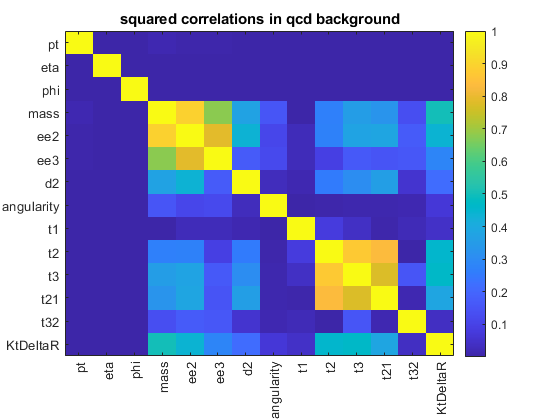


figure
imagesc(qcd_data_correlations.^2)
title('squared correlations in qcd background')
xtick_values = 1:14;
ytick_values = 1:14;
set(gca, 'Xtick', xtick_values, 'XTickLabel', feature_labels)
set(gca, 'Ytick', ytick_values, 'YTickLabel', feature_labels)
xtickangle(90)
colorbar

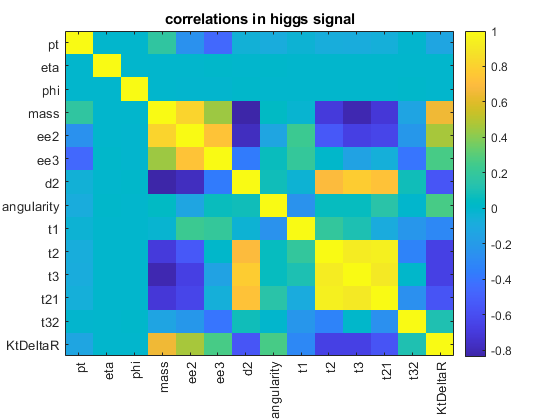


figure;
imagesc(higgs_data_correlations)
title('correlations in higgs signal')
xtick_values = 1:14;
ytick_values = 1:14;
set(gca, 'Xtick', xtick_values, 'XTickLabel', feature_labels)
set(gca, 'Ytick', ytick_values, 'YTickLabel', feature_labels)
xtickangle(90)
colorbar

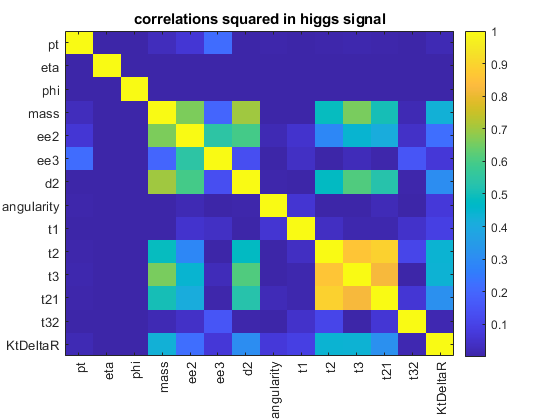


figure
imagesc(higgs_data_correlations.^2)
title('correlations squared in higgs signal')
xtick_values = 1:14;
ytick_values = 1:14;
set(gca, 'Xtick', xtick_values, 'XTickLabel', feature_labels)
set(gca, 'Ytick', ytick_values, 'YTickLabel', feature_labels)
xtickangle(90)
colorbar